# Comparing Truth Models

% bringing in simulation data and provided data
load sim_setup.mat
load orbitdetermination-finalproj_data_2023_11_14.mat
% Bringing in required functions and variables 
addpath('./functions/')

## Simulation Settings and Useful Constants

m = length(a_SRP);                      % number of inputs equals the length of this vector
p = 2;                                  % number of measurement variables per landmark
x_0 = [r_nom; dr_nom];                  % initial state
n = length(x_0);                        % number of state variables
dt = dt_int;                            % chosen step size
% dt = dt_obs; 
t_obs = unique(y_table(:, 1));          % times of observations [s]
t = -dt:dt:max(t_obs);                    % time vector for LKF
steps = length(t);                      % number of time steps in used in LKF
steps_obs = length(t_obs);

% --- number of landmarks to use --- 
num_marks = length(pos_lmks_A);
lps = pos_lmks_A(:,1:num_marks);

## System Matrices and Noise

These are static

% --- Static system matrices ---
% CT B matrix
B = zeros(n,m);
B(4:end,:) = eye(3);

% Static input
u = a_SRP;

% CT Gamma matrix 
Gamma = zeros(n,m);
Gamma(4:end,:) = eye(3);

% CT Noise matrices
W_truth = eye(m)*sig_w^2;
W = eye(m)*sig_w^2*1e5;
V = eye(p)*sig_v^2;
R = V/dt;

## Inital Uncertainties and Pertibations

% -- initial uncertainty and pertibations --- 
pos_uncert = ones(1,3)*1e-4;                  % position 2-sigma uncertainty on order of meters
vel_uncert = ones(1,3)*1e-6;                            % velocity '                           ' of mm/s
P_0 = diag([pos_uncert.^2/4,vel_uncert.^2/4]);  % Initial uncertainty matrix
x_pert = mvnrnd(zeros(n,1),P_0)';               % Random initial uncertainty gerated from uncertainty matrix

## State Truth Models

Using different methods

### Ode45 Truth States Generation: No Noise

Simply Solving the ode for all of time with the given "truth" initial conditions. Naive, with no noise at all in the system. 

If the initial state is wrong, then all subsequent nominal states are wrong. 

% pure ODE solution with no noise
options = odeset('RelTol',1e-12);               % ODE45 options
[~,x_ode_clean] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t, x_0', options);

### Ode45 Truth StatesGeneration: With Noise

While the initial condition at time $t = 0$ remains the truth condition, the continious time noise is added at each time step in the driving equations. 

I don't think this one is correct. At each time step, the noise is added as a sort of "sample and hold", which will result in incorrect continuous time ODE solutions. In short, the governing equations do not reflect the equations of motion. Instead, they represent the non-noisy equations of motion, with a different pertibation vector at each solution point. Each ode solution is solving a slightly different ODE that does not reflect reality.

% --- Truth Model ---
% Non-linear simulation with noise, producing measurements
% This serves as the truth of the system 

% Performing non-linear simulation with added noise
x_ode_noisy = zeros(steps,n);                       % initializing state vector
x_ode_noisy(1,:) = x_0';
for k = 2:steps-1
    % Calculating true state with noise, based on non-linear ODE solver 
    % Solving the ODE over this time step
    [t_ode,x_ode45] = ode45(@(t_in,x_in) orbit_noise(t_in,x_in,a_SRP,mu_A,W_truth), [t(k-1), t(k+1)], x_ode_noisy(k-1,:), options);
    [~,k_idx] = min(abs(t_ode-t(k)));
    x_ode_noisy(k,:) = x_ode45(k_idx,:);
end

### DT LTI Truth States Generation: Process Noise, but clean nominal state

This is a regular DT LTI model solving for pertibations around the nominal state, where the nominal state is taken to be the ode45 solution with no noise. 

I think this is also wrong. While this adds noise around the truth state, the noise pertibations are not propagated to the next nominal state.

rng(100)                                % Seed for the noise creation seed
seeds = round(rand([1,steps]) * 100);   % used to make sure the input noise is the same each time 

dx_DT = zeros(steps,n); 
dx_DT(1,:)= x_pert';
x_DT = zeros(steps,n);
x_DT(1,:) = x_0';
for k = 1:steps-1
    % calculating nominal state
    x_nom_k = x_ode_clean(k,:)';
    
    % Jacobians for nominal state
    A = dfdx(x_nom_k,mu_A);

    % Putting this in the discrete time 
    [F,G,Q] = state_CT_to_DT(dt,A,B,Gamma,W_truth);
    rng(seeds(k))
    w_k = mvnrnd(zeros(n,1),Q)';

    % deviation at the next time step
    dx_k_plus = F*dx_DT(k,:)'+ G*u + w_k;

    % saving these 
    dx_DT(k+1,:) = dx_k_plus';
    x_DT(k+1,:) = x_nom_k' + dx_k_plus';
end

### DT LTI Truth States Generation: Process Noise, but clean nominal state

This is a regular DT LTI model solving for pertibations around the nominal state, where the nominal state is taken to be the ode45 solution with no noise. 

I think this is also wrong. While this adds noise around the truth state, the noise pertibations are not propagated to the next nominal state.

rng(100)                                % Seed for the noise creation seed
seeds = round(rand([1,steps]) * 100);   % used to make sure the input noise is the same each time 

dx_DT = zeros(steps,n); 
dx_DT(1,:)= x_pert';
x_DT_2 = zeros(steps,n);
x_DT_2(1,:) = x_0';
for k = 1:steps-1
    % calculating nominal state
    x_nom_k = x_ode_clean(k,:)';
    
    % Jacobians for nominal state
    A = dfdx(x_nom_k,mu_A);

    % Putting this in the discrete time 
    [F,G,Q] = state_CT_to_DT(dt,A,B,Gamma,W_truth);
    rng(seeds(k))
    w_k = mvnrnd(zeros(n,1),Q)';

    % deviation at the next time step
    dx_k_plus = F*dx_DT(k,:)'+ G*u + w_k;

    % saving these 
    dx_DT(k+1,:) = dx_k_plus';
    x_DT_2(k+1,:) = x_ode_clean(k+1,:) + dx_k_plus';
end

### DT LTI Truth States Generation: Process Noise, but DT LTI Calculated Nominal State

This ueses 

dx_DT = zeros(steps,n); 
dx_DT(1,:)= x_pert';
x_DT_noise = zeros(steps,n);
x_DT_noise(1,:) = x_0';
for k = 1:steps-1
    % calculating nominal state
    x_nom_k = x_DT_noise(k,:)';
    
    % Jacobians for nominal state
    A = dfdx(x_nom_k,mu_A);

    % Putting this in the discrete time 
    [F,G,Q] = state_CT_to_DT(dt,A,B,Gamma,W_truth);
    w_k = mvnrnd(zeros(n,1),Q)';

    % deviation at the next time step
    dx_k_plus = F*dx_DT(k,:)'+ G*u + w_k;

    % saving these 
    dx_DT(k+1,:) = dx_k_plus';
    x_DT_noise(k+1,:) = x_nom_k' +  dx_k_plus';
end

### DT LTI Truth States Generation: Process Noise, but Nominal State re-generated each time

dx_DT = zeros(steps,n); 
dx_DT(1,:)= x_pert';
x_DT_dynamic_nom= zeros(steps,n);
x_DT_dynamic_nom(1,:) = x_0';
for k = 2:steps
    % calculating nominal state
    [~,x_ode] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), [t(k-1), t(k)], x_DT_dynamic_nom(k-1,:)', options);
    x_nom_k = x_ode(end,:)';

    % Jacobians for nominal state
    A = dfdx(x_nom_k,mu_A);

    % Putting this in the discrete time 
    [F,G,Q] = state_CT_to_DT(dt,A,B,Gamma,W_truth);
    w_k = mvnrnd(zeros(n,1),Q)';

    % deviation at the next time step
    dx_k_plus = F*dx_DT(k-1,:)'+ G*u + w_k;

    % saving these 
    dx_DT(k,:) = dx_k_plus';
    x_DT_dynamic_nom(k,:) = x_nom_k' +  dx_k_plus';
end

### Comparing the state truth models

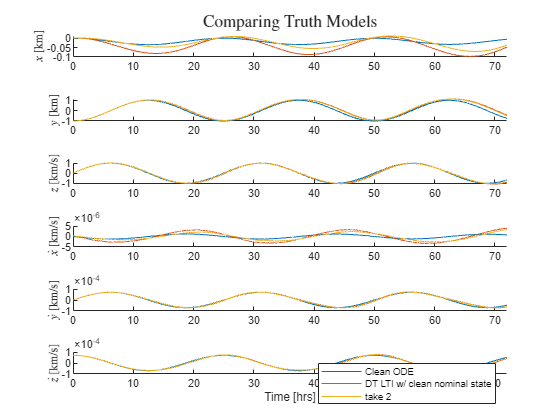

figure;
fig = tiledlayout(n,1);
ylabels =   ["$ x$ [km]", "$ y$ [km]","$z$ [km/s]", ...
            "$\dot x$ [km/s]", "$\dot y$ [km/s]","$\dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    hold on
    plot(t/60/60,x_ode_clean(:,i))
    plot(t/60/60,x_DT(:,i))
    plot(t/60/60,x_DT_2(:,i))
    hold off
    xlim([t_obs(1)/60/60, 72])
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"Comparing Truth Models", Interpreter='latex')
% legend("Clean ODE",'Noisy ODE','DT LTI w/ clean nominal state','Recursive DT LTI')
legend("Clean ODE",'DT LTI w/ clean nominal state','take 2')